#      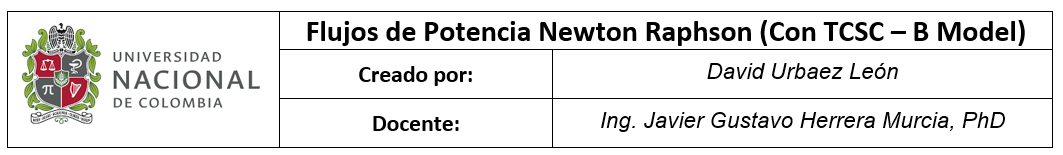

### 1)    Se definen las bases del sistema

-  Potencia base $S_b ={100\cdot 10}^{6\;}$[VA]

-  Voltaje base   $V_b ={230\cdot 10}^{3\;}$[V]

Sb = 100e6; %[VA]
Vb = 230e3; %[V]

### 2)    Se crean las matrices  con la información de la red ( br_data, N_data):

Se deben crear dos matrices para ingresar la información referente al circuito. La primera (br_data) brinda información acerca de las conexiones entre buses como la impedancia de la línea o los buses entre los cuales se realiza la conexión , mientras que la segunda (N_data) da información acerca de la naturaleza de cada uno de los buses, tipo de bus (SL, PV o PQ).

a) Para la matriz **br_data** se tiene que el formato es

                    
$$\mathrm{br}_\mathrm{data}=\left\lbrack {\mathrm{Bus}}_{\mathrm{from}\;} ,{\mathrm{Bus}}_{\mathrm{to}} ,R,X,G,B\right\rbrack \;\mathrm{in}\;p\ldotp u\ldotp$$


b) Para la matriz **N_data **se tiene que el formato es:

                  
$$N_‾‾\mathrm{data}=\left\lbrace \mathrm{#Bus},\mathrm{type}\left(\prime \mathrm{SL}\prime ,\prime \mathrm{PQ}\prime ,\prime \mathrm{PV}\prime \right),V\left\lbrack p\ldotp u\ldotp \right\rbrack ,\angle \mathrm{Vº},\mathrm{PG}\left\lbrack p\ldotp u\ldotp \right\rbrack ,\mathrm{QG}\left\lbrack p\ldotp u\ldotp \right\rbrack ,\mathrm{PL}\left\lbrack p\ldotp u\ldotp \right\rbrack ,\mathrm{QL}\left\lbrack p\ldotp u\ldotp \right\rbrack \right\rbrace$$


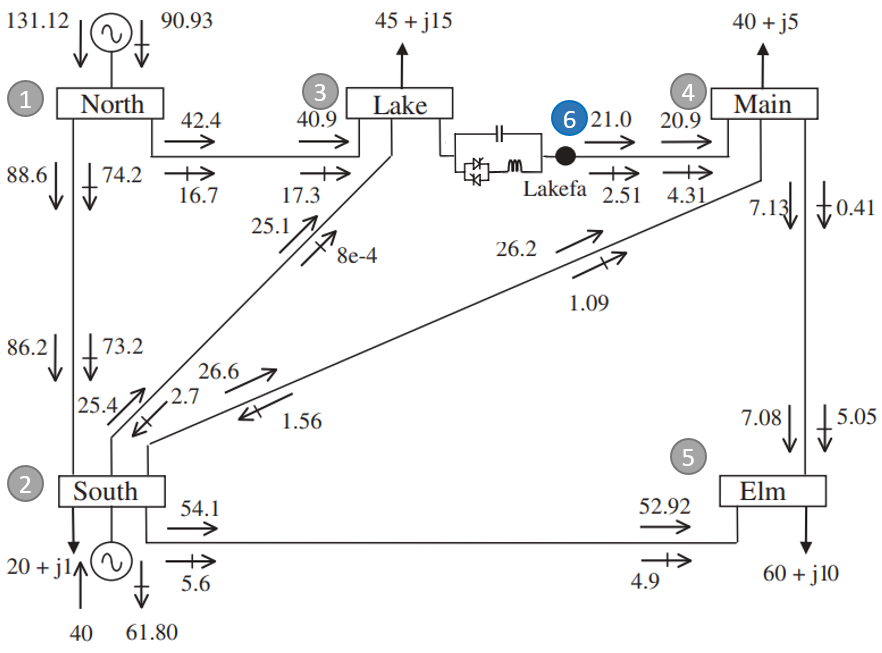

% Branches data R, X, G, B
% Types: General in form of impedance. (G & B are split in half at both ends).

     


% Node definitions
% {  #, type,   Vpu,    <Vº,   PG pu,  QG pu,  PL pu, QL pu}
N_data = {
    1,  'SL',   1.06,   0.0,    0.0,    0.0,    0.00,    0.00;
    2,  'PV',   1.0,    0.0,    0.4,    0.0,    0.20,    0.10;
    3,  'PQ',   1.0,    0.0,    0.0,    0.0,    0.45,    0.15;
    4,  'PQ',   1.0,    0.0,    0.0,    0.0,    0.40,    0.05;
    5,  'PQ',   1.0,    0.0,    0.0,    0.0,    0.60,    0.10;
    6,  'PQ',   1.0,    0.0,    0.0,    0.0,    0.00,    0.00 }; % Se crea el nodo 6 (Lakefa)


% br_data=[ bus1, bus2,   R ,      X ,     G ,     B  ] in p.u.
br_data = [ 1,      2,  0.02,    0.06,    0.0,    0.06;
            1,      3,  0.08,    0.24,    0.0,    0.05;
            2,      3,  0.06,    0.18,    0.0,    0.04;
            2,      4,  0.06,    0.18,    0.0,    0.04;
            2,      5,  0.04,    0.12,    0.0,    0.03;
            6,      4,  0.01,    0.03,    0.0,    0.02;  % || Se modifica la conexión nodo 3-4 a 6-4 ||
            4,      5,  0.08,    0.24,    0.0,    0.05];
        

br_data=array2table(br_data,'VariableNames',{'FromBus','ToBus','R','X','G','B'});
N_data=cell2table(N_data,'VariableNames',{'n','type','Vm','Va','PG','QG','PL','QL'});

% THYRISTOR CONTROLLED SERIES COMPENSATOR reactance variable
% NTCSC : Number of TCSC’s
% TCSCsend : Sending bus
% TCSCrec : Receiving bus
% X : TCSC’s reactance
% XLo : Lower reactance limit
% XHi : Higher reactance limit
% Flow : Power flow direction: 1 is for sending to receiving bus; -1
% indicates opposite direction
% Psp : Active power flow to be controlled
% status : Indicates control status for active power: 1 is on and 0 is off

% TCSC_data= [TCSCsend,TCSCrec,     X  ,  XLo  ,   XHi ,  Psp  , Flow, status];
TCSC_data  = [    3   ,   6   , -0.015 , -0.05 ,  0.05 ,  0.21 ,   1 ,   1   ];

TCSC_data=array2table(TCSC_data,'VariableNames',{'TCSCsend','TCSCrec','X','Xmin','Xmax','Psp','Flow','Status'})

TCSC_data = 1×8 table
    TCSCsend    TCSCrec      X       Xmin     Xmax    Psp     Flow    Status
    ________    _______    ______    _____    ____    ____    ____    ______

       3           6       -0.015    -0.05    0.05    0.21     1        1   


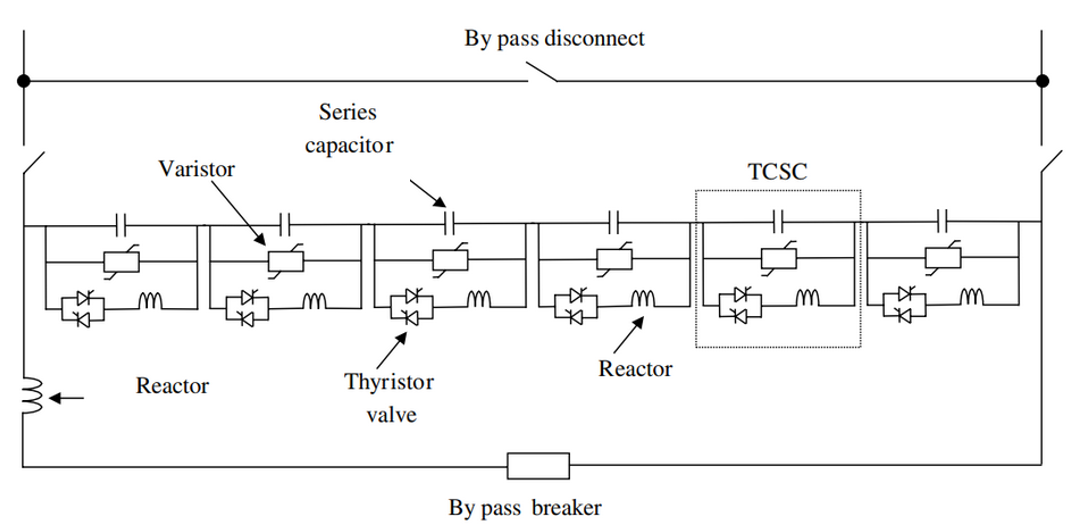(Fig 2.6 - Pag 19, Acha)

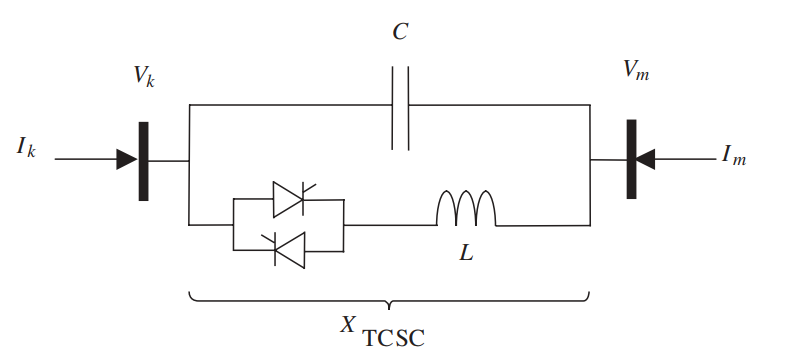(Fig 2.12 - Pag 27, Acha)

### 3)      Se crea Ybus con las redes de 2 puertos:

                Se tiene la siguiente red de dos puertos, que representa el circuito del modelo pi de la línea de transmisión

                                
$$\left\lbrack \begin{array}{c}
V_i \\
V_j 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\frac{1}{z}+\frac{y}{2} & -\frac{1}{z}\\
-\frac{1}{z} & \frac{1}{z}+\frac{y}{2}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
I_i \\
I_j 
\end{array}\right\rbrack$$


                                        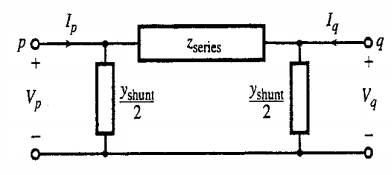

                       Pi-equvalent model of a transmission line  *(Pag 296, Bergen)*

n_br = size(br_data, 1); % Number of branches
num_nodes = max(max([br_data.FromBus,br_data.ToBus]));  % Number of nodes (starting at 1)
Ybus = zeros(num_nodes, num_nodes); % Empty Ybus Matrix

for kk = 1: size(br_data, 1)    % Iter over branch Data
    ii = br_data.FromBus(kk);               % From bus
    jj = br_data.ToBus(kk);                 % To Bus
    z = br_data.R(kk) + 1j * br_data.X(kk);  % Line impedance
    y = br_data.G(kk) + 1j * br_data.B(kk);  % Shunt admitance
    
    Ybr=[1 / z + y / 2 ,    -1 / z;  ...     % Ybr (Two-Port Network)
            -1 / z     , 1 / z + y / 2];

    Ybus([ii,jj],[ii,jj]) = Ybus([ii,jj],[ii,jj])+ Ybr;                       % Add the Two-Port Network to the global Ybus Matrix
end

Se extrae la información de las potencias y voltajes:

Vm_sp = N_data.Vm;              %   [V]  Specified Voltages
th_sp = N_data.Va.* pi ./ 180; % [Rads] Specified Angles
PG = N_data.PG;                 % [p.u.] Active Power generators
QG = N_data.QG;                 % [p.u.] Reactive Power generators

PL = N_data.PL;                 % [p.u.] Active Power Loads
QL = N_data.QL;                 % [p.u.] Reactive Power Loads

P_sp = PG - PL;                      % [p.u.] Specified Active Power    Pnet= (PGen - PLoad)
Q_sp = QG - QL;                      % [p.u.] Specified Reactive Power  Qnet= (QGen - QLoad)

### 4) Construcción de la matriz Jacobiana

Se encuentran las dimensiones de la matriz jacobiana:

% Jacobian matrix size.

nL = sum(strcmp(N_data.type,'PQ'));% Number of PQ nodes  (#Loads)
nG = sum(strcmp(N_data.type,'PV'));% Number of PV nodes  (#Generators)



Se divide la matriz Jacobiana en la submatrices H-N-M-L

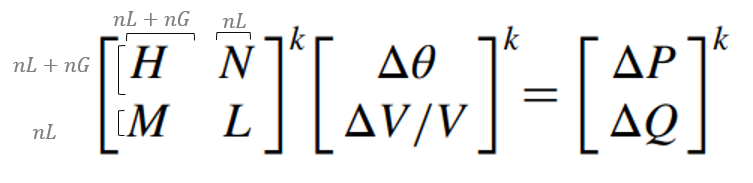

                                                                             *(Eq. 3.32, pag108, Gómez - Exposito)*

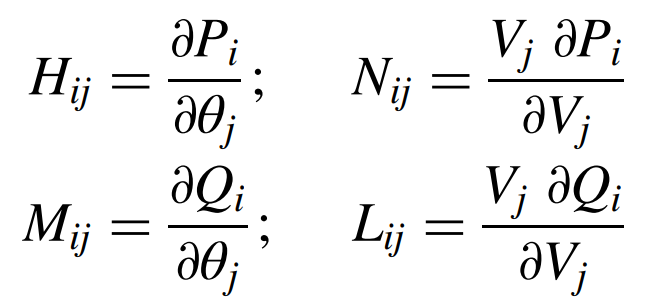

*                                                                     (Eq. 3.34, pag109, Gómez - Exposito)*

H = zeros( nL + nG, nL + nG );
L = zeros( nL, nL );
N = zeros( nL + nG , nL );
M = zeros( nL , nL + nG );
J = [H, N; M, L];

Se crea el vector de estados ($X={\left\lbrack \theta |V\right\rbrack }^T$) y el vector de funciones no lineales ($f\left(x\right)=\left\lbrack \Delta P|\Delta Q\right\rbrack$

x_th = zeros( nL + nG, 1 ); % State vector for storing angles (theta)
x_v = zeros( nL , 1);       % State vector for storing Voltages

     dim= (2nL+nG)

x = [x_th; x_v];

-     Donde se tiene que:

                        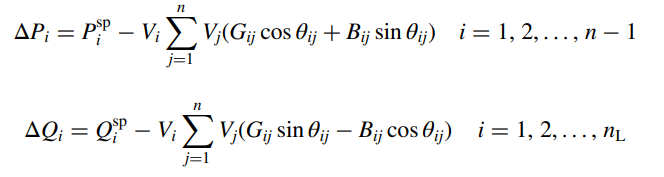

*                                                                                                                        (Eq. 3.30-3.31, pag108, Gómez - Exposito)*

Dt_P = zeros( nL + nG, 1 ); % Delta P 
Dt_Q = zeros( nL, 1);       % Delta Q

                dim= (2nL+nG)

Dt = [Dt_P;Dt_Q];  %Delta Vector (same as f(x) Vector)

%% Define Unkown Values (Voltage and angle in PQ node - Angle in PV node)
% #Buses with unknwon voltage magnitudes ('PQ' buses)  (Delta Q index)
x_v_n=N_data(strcmp(N_data.type,'PQ'),:).n;                          

% #Buses with unknwon voltage angles ('PQ'|'PV' buses) (Delta P index)
x_th_n=N_data(strcmp(N_data.type,'PV')|strcmp(N_data.type,'PQ'),:).n;


x_n = [x_th_n; x_v_n]; % #Buses with unknown Angles and unknown voltages

max_iter = 100; %Define Max iteration number

V = zeros(num_nodes, max_iter);     % Matrix for storing node voltages per iter
Vm = zeros(num_nodes, max_iter);    % For storing node voltage magnitude per iter
th = zeros(num_nodes, max_iter);    % For storing node voltage angles per iter
V(:,1) = Vm_sp .* exp(1j .* th_sp); % Fill with initial Specified Voltages
Vm(:,1) = Vm_sp;                    % Fill with initial Specified Magnitud
th(:,1) = th_sp;                    % Fill with initial Specified Angle

err = 1.0;  % Define Error
k = 1;      % iteration counter

## 5) Inicia el método Newton Raphson


while (err > 1e-12 && k < max_iter)
% for cc = 1 : 3
   
    % *************************** Jacobian Terms Calculation.
    Vn = V( : , k ); %Phasors!!
    Vd = diag( Vn ); %Voltages in a diagonal matrix
    
    % Calculate active and reactive power per node
    Sn = Vd * conj( Ybus * V( : , k ) ); %  Sn=V(I)* | I=Y_bus·V | Sn=V·(Ybus·V)*
    Pn = real(Sn);  %Active Power calculated
    Qn = imag(Sn);  % Reactive Power calculated

   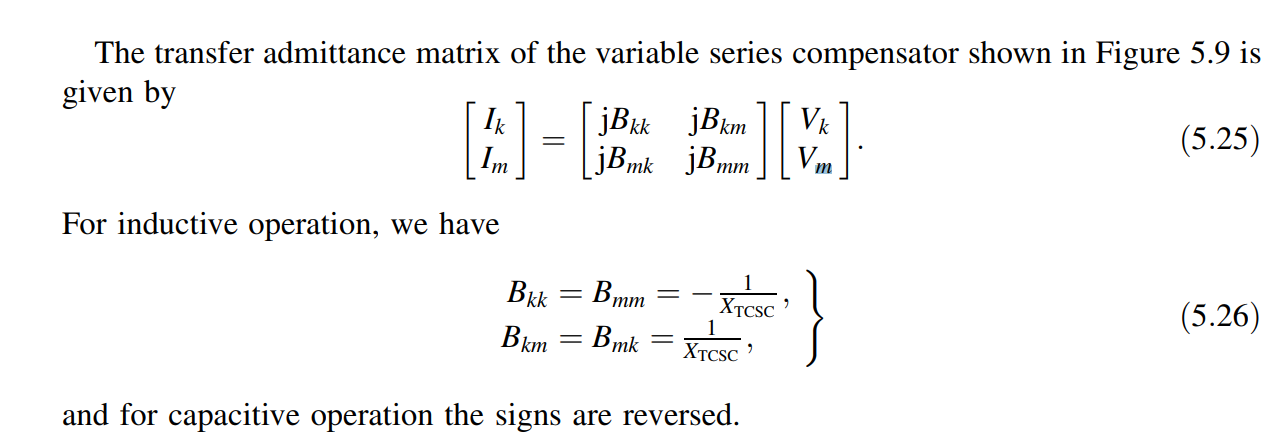

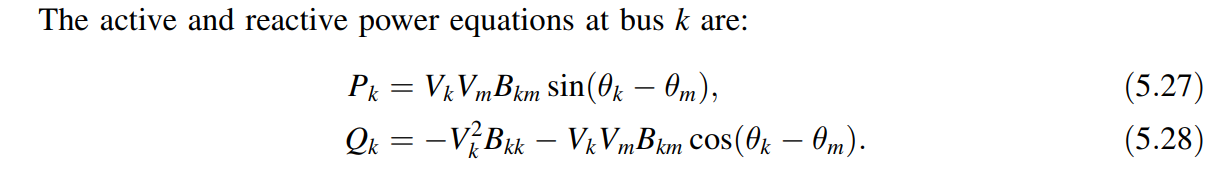

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %% TCSC Calculated Power
    
    for n=1:size(TCSC_data,1)
        Bmm=-1/TCSC_data{n,'X'};
        Bmk= 1/TCSC_data{n,'X'};
        
        for kk=1:2 % for node k - node m
            
            % Angle difference between TCSC nodes
            A=th(TCSC_data{n,"TCSCsend"},k)-th(TCSC_data{n,"TCSCrec"},k);
            
            % Apparent Power at TCSC sending node
            Pcal=Vm(TCSC_data{n,"TCSCsend"},k)*Vm(TCSC_data{n,"TCSCrec"},k)*Bmk*sin(A);
            Qcal=-Vm(TCSC_data{n,"TCSCsend"},k)^2*Bmm...
                 -Vm(TCSC_data{n,"TCSCsend"},k)*Vm(TCSC_data{n,"TCSCrec"},k)*Bmk*cos(A);

            % Update Apparent Power at TCSC sending node
            Pn(TCSC_data{n,"TCSCsend"})= Pn(TCSC_data{n,"TCSCsend"}) + Pcal;
            Qn(TCSC_data{n,"TCSCsend"})= Qn(TCSC_data{n,"TCSCsend"})  + Qcal;
            
            if kk==1
                TCSC_data{n,"TCSC_PQsend"}=Pcal + 1j*Qcal;
            else
                TCSC_data{n,"TCSC_PQrec"} = Pcal + 1j*Qcal;
            end
            
            % Switch send - rec definition
            send=TCSC_data{n,"TCSCsend"};
            TCSC_data{n,"TCSCsend"} = TCSC_data{n,"TCSCrec"};
            TCSC_data{n,"TCSCrec"}  = send;
        end
    end

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    

Se calculan los términos residuales.

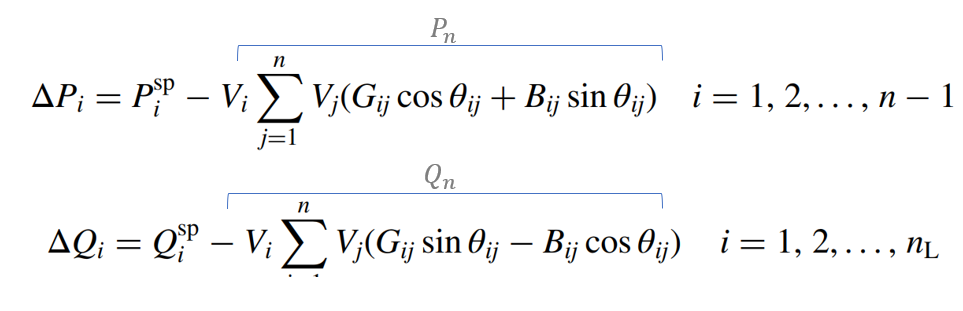

    % *************************** Residual Terms Calculations

    % Delta P
    Dt_P=P_sp(x_th_n(1:nL+nG))-Pn(x_th_n(1:nL+nG));
    % Delta Q
    Dt_Q=Q_sp(x_v_n(1:nL))-Qn(x_v_n(1:nL));

   
    Dt = [ Dt_P ;...
           Dt_Q ];

Se calcula el error en la potencia sobre el TCSC

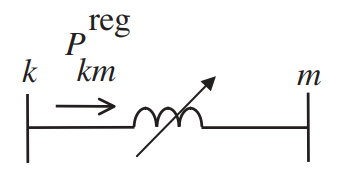

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%           TCSC Power Mismatches
    if k > 1
        for n = 1:size(TCSC_data,1)
            
            if TCSC_data{n,'Status'} == 1
                Bmk = 1/TCSC_data{n,'X'};
                
                for kk = 1:2
                     % Angle difference between TCSC nodes
                     A=th(TCSC_data{n,"TCSCsend"},k)-th(TCSC_data{n,"TCSCrec"},k);
                     
                     Pcal=Vm(TCSC_data{n,"TCSCsend"},k)*Vm(TCSC_data{n,"TCSCrec"},k)*Bmk*sin(A);
                     
                     if (TCSC_data{n,'Flow'} == 1 && kk == 1) || (TCSC_data{n,'Flow'} == -1 && kk == 2)
                         Dt(2*nL+nG+n) = TCSC_data{n,'Psp'}-Pcal;
                         break;
                     end
                     
                     % Switch send - rec definition
                     send = TCSC_data{n,"TCSCsend"};
                     TCSC_data{n,"TCSCsend"} = TCSC_data{n,"TCSCrec"};
                     TCSC_data{n,"TCSCrec"}  = send;
                end
            else
                Dt(2*nL+nG+n) = 0; % Add Zero Mismatch delta(Pkm)=0
            end
        end
    end

%% Find Jacobian    

Se obtienen las matrices H,L,N,M donde:

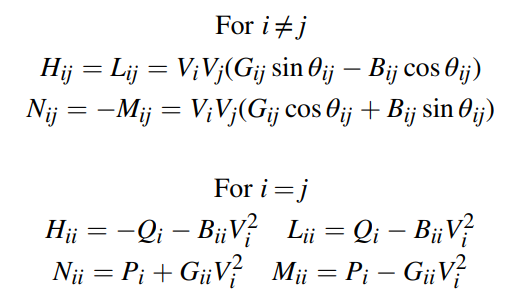

*                                                                                                                                                                                   (Table 3.1, pag109, Gómez - Exposito)*

  % H Matrix.   H -> Dim: (nL+nG) X (nL+nG)
    
    for mm = 1 : nL + nG        %Iter over rows H matrix
        for nn = 1 : nL + nG    %Iter over cols H matrix
            ii = x_th_n(mm);    % #node corresponding to row mm
            jj = x_th_n(nn);    % #node corresponding to column nn
            
            % From Prev Equations:
            if ii == jj
                H(mm,nn) = - Qn(ii) - imag( Ybus(ii,jj) ) .* abs( V(ii,k) ).^2;
            else
                H(mm,nn) = abs( V(ii,k) ) * abs( V(jj,k) ) .* ( ...
                    real(Ybus(ii,jj)) * sin( th(ii,k) - th(jj,k) ) - ...
                    imag(Ybus(ii,jj)) * cos( th(ii,k) - th(jj,k) ) );
            end
        end
    end
   
    % N Matrix. N -> Dim: (nL+nG) X (nL)
    for mm = 1 : nL + nG     %  Iter over rows N matrix
        for nn = 1 : nL      %  Iter over cols N matrix
            ii = x_th_n(mm); % #node corresponding to row mm
            jj = x_v_n(nn);  % #node corresponding to column nn
           
            % From Prev Equations:
            if ii == jj
                N(mm,nn) = Pn(ii) + real(Ybus(ii,jj)) .* abs(V(ii,k)).^2;
            else
                N(mm,nn) = abs( V(ii,k) ) * abs( V(jj,k) ) .* ( ...
                    real(Ybus(ii,jj)) * cos( th(ii,k) - th(jj,k) ) + ...
                    imag(Ybus(ii,jj)) * sin( th(ii,k) - th(jj,k) ) );
            end
        end
    end
   
    % M Matrix. M -> Dim: (nL) X (nL+nG)
    for mm = 1 : nL             %  Iter over rows M matrix
        for nn = 1 : nL + nG    %  Iter over cols M matrix
            ii = x_v_n(mm);     % #node corresponding to row mm
            jj = x_th_n(nn);    % #node corresponding to column nn
            
            % From Prev Equations:
            if ii == jj
                M(mm,nn) = Pn(ii) - real(Ybus(ii,jj)) .* abs(V(ii,k)).^2;
            else
                M(mm,nn) = -abs( V(ii,k) ) * abs( V(jj,k) ) .* ( ...
                    real(Ybus(ii,jj)) * cos( th(ii,k) - th(jj,k) ) + ...
                    imag(Ybus(ii,jj)) * sin( th(ii,k) - th(jj,k) ) );
            end
        end
    end

    % L Matrix. L -> Dim: (nL) X (nL)
    for mm = 1 : nL         %  Iter over rows L matrix
        for nn = 1 : nL     %  Iter over cols L matrix
            ii = x_v_n(mm); % #node corresponding to row mm
            jj = x_v_n(nn); % #node corresponding to column nn
            
            % From Prev Equations:
            if ii == jj
                L(mm,nn) = Qn(ii) - imag(Ybus(ii,jj)) .* abs(V(ii,k)).^2;
            else
                L(mm,nn) = abs( V(ii,k) ) * abs( V(jj,k) ) .* ( ...
                    real(Ybus(ii,jj)) * sin( th(ii,k) - th(jj,k) ) - ...
                    imag(Ybus(ii,jj)) * cos( th(ii,k) - th(jj,k) ) );
            end
        end
    end
   % The jacobian matrix results in:
    J = [H, N;...
        M, L];

Se agregan valores al jacobiano de la conexión del TCSC.

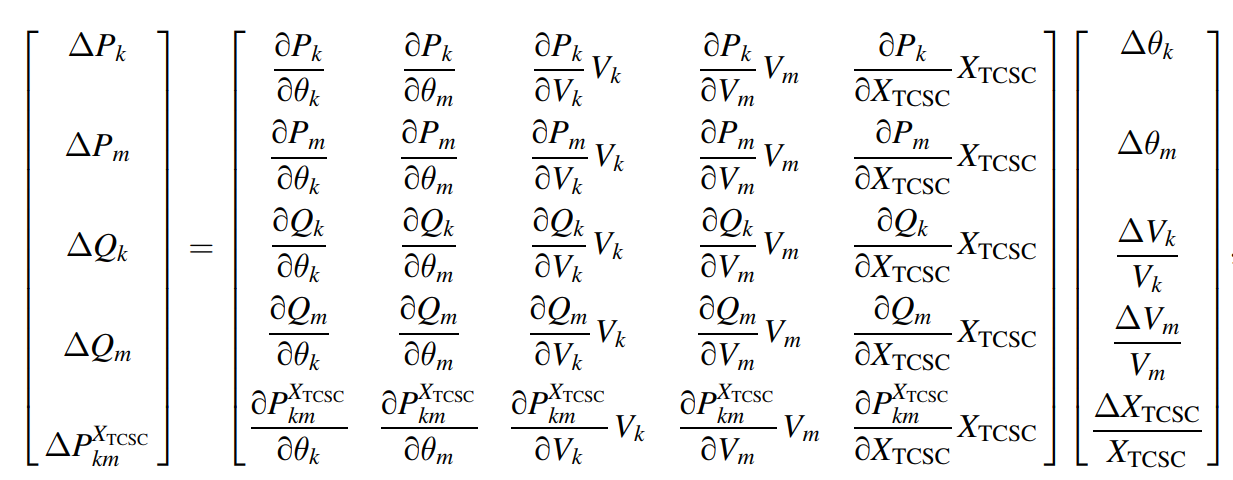

Es decir, se debe agregar al jacobiano las componentes correspondientes a $X_{\mathrm{TCSC}}$ (notar que $B_{\mathrm{km}}$=-$B_{\mathrm{mm}}$ )

    Se define:

          
$$\begin{array}{l}
{H_{\mathrm{km}\;} =-V}_k V_{m\;} B_{\mathrm{mm}} \mathrm{cos}\left(\theta_k -\theta_m \right)\\
{N_{\mathrm{km}\;} =\;\;\;\;\;V}_k V_{m\;} B_{\mathrm{mm}} \mathrm{sin}\left(\theta_k -\theta_m \right)
\end{array}$$


 ---------------------------------------------------------------------

    
$$\frac{\partial P_k }{\partial \theta_k }=-V_k^2 B_{\mathrm{kk}}$$


    
$$\frac{\partial P_k }{\partial \theta_m }={-V}_k V_{m\;} B_{\mathrm{km}} \mathrm{cos}\left(\theta_k -\theta_m \right)=V_k V_{m\;} B_{\mathrm{mm}} \mathrm{cos}\left(\theta_k -\theta_m \right)={-H}_{\mathrm{km}}$$


    
$$\frac{\partial P_k }{\partial V_{m\;} }=V_k V_m B_{\mathrm{km}} \mathrm{sin}\left(\theta_k -\theta_m \right)=-V_k V_m B_{\mathrm{mm}} \mathrm{sin}\left(\theta_k -\theta_m \right)=-N_{\mathrm{km}\;}$$


    
$$\frac{\partial P_k }{\partial V_k }=V_k^2 G_{\mathrm{kk}} =0$$


    ---------------------------------------------------------------------

    
$$\frac{\partial Q_k }{\partial V_k }=-V_k^2 B_{\mathrm{kk}}$$


    
$$\frac{\partial Q_k }{\partial \theta_m }={-V}_k V_m B_{\mathrm{km}} \mathrm{sin}\left(\theta_k -\theta_m \right)=V_k V_m B_{\mathrm{mm}} \mathrm{sin}\left(\theta_k -\theta_m \right)=N_{\mathrm{km}\;}$$


    
$$\frac{\partial Q_k }{\partial V_{m\;} }={-V}_k V_{m\;} B_{\mathrm{km}} \mathrm{cos}\left(\theta_k -\theta_m \right)=V_k V_{m\;} B_{\mathrm{mm}} \mathrm{cos}\left(\theta_k -\theta_m \right)={-H}_{\mathrm{km}}$$


    $\frac{\partial Q_k }{\partial \theta_k }=-V_k^2 G_{\mathrm{kk}} =0$                                                                     (Eq 4.30-4.37 , Acha)

 ---------------------------------------------------------------------

    Recordando que:

    
$$B_{\mathrm{km}} =B_{\mathrm{mk}} =-B_{\mathrm{kk}} =-B_{\mathrm{mm}} =\frac{1}{X_{\mathrm{TCSC}} }$$
    

         
$${P_k =V}_k V_m B_{\mathrm{mk}} \mathrm{sin}\left(\theta_k -\theta_m \right)=\frac{V_k V_m \;\mathrm{sin}\left(\theta_k -\theta_m \right)}{X_{\mathrm{TCSC}} }$$


        
$${Q_k =-V_k^2 B_{\mathrm{km}} -V}_k V_m B_{\mathrm{mk}} \mathrm{cos}\left(\theta_k -\theta_m \right)=-\frac{V_k^2 }{X_{\mathrm{TCSC}} }-\frac{V_k V_m \;\mathrm{cos}\left(\theta_k -\theta_m \right)}{X_{\mathrm{TCSC}} }$$


Se encuentra que:


$$\frac{\partial P_k }{\partial X}X=-\frac{V_k V_m \mathrm{sin}\left(\theta_k -\theta_m \right)}{{X_{\mathrm{TCSC}} }^2 }\left(X_{\mathrm{TCSC}} \right)=-\frac{V_k V_m \mathrm{sin}\left(\theta_k -\theta_m \right)}{X_{\mathrm{TCSC}} }=V_k V_m B_{\mathrm{mm}} \mathrm{sin}\left(\theta_k -\theta_m \right)=-N_{\mathrm{km}}$$



$$\frac{\partial Q_k }{\partial X}X=\left(+\frac{V_{\mathrm{kk}}^2 }{X_{\mathrm{TCSC}}^2 }+\frac{V_k V_m \mathrm{cos}\left(\theta_k -\theta_m \right)}{{X_{\mathrm{TCSC}} }^2 }\right)\left(X_{\mathrm{TCSC}} \right)=+\frac{V_{\mathrm{kk}}^2 }{X_{\mathrm{TCSC}} }+\frac{V_k V_m \mathrm{cos}\left(\theta_k -\theta_m \right)}{X_{\mathrm{TCSC}} }={-V}_{\mathrm{kk}}^2 B_{\mathrm{mm}} -V_k V_m B_{\mathrm{mm}} \mathrm{cos}\left(\theta_k -\theta_m \right)=$$

$$H_{\mathrm{km}} {-V}_{\mathrm{kk}}^2 B_{\mathrm{mm}}$$


$\frac{\partial P_{\mathrm{km}} }{\partial X}X$=$\frac{\partial P_k }{\partial X}X$

     (Appendix A Section A.2 , Acha)

   %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
   %%               TCSC JACOBIAN UPDATE
   
    for n=1:size(TCSC_data,1)
        Bmm=-1/TCSC_data{n,'X'};
        Bmk= 1/TCSC_data{n,'X'};
        
        for kk=1:2 % for node k - node m
            
            DP_send_Index = find(x_th_n==TCSC_data{n,'TCSCsend'});% get delta(P) index of the TCSC send node
            DQ_send_Index = find(x_v_n==TCSC_data{n,'TCSCsend'}); % get delta(Q) index of the TCSC send node
            
            DP_rec_Index = find(x_th_n==TCSC_data{n,'TCSCrec'});% get delta(P) index of the TCSC rec node
            DQ_rec_Index = find(x_v_n==TCSC_data{n,'TCSCrec'}); % get delta(Q) index of the TCSC rec node
            
            
            
            % Angle difference between TCSC nodes
            A=th(TCSC_data{n,"TCSCsend"},k)-th(TCSC_data{n,"TCSCrec"},k);
            
            
            Hkm=-Vm(TCSC_data{n,"TCSCsend"},k)*Vm(TCSC_data{n,"TCSCrec"},k)*Bmm*cos(A);
            Nkm= Vm(TCSC_data{n,"TCSCsend"},k)*Vm(TCSC_data{n,"TCSCsend"},k)*Bmm*sin(A);
            
            %% Jacobians Update
            
            % dPk/dAk
            J(DP_send_Index,DP_send_Index)            = J(DP_send_Index,DP_send_Index)...
                                                        -Vm(TCSC_data{n,"TCSCsend"},k)^2*Bmm;
            % dPk/dAm
            J(DP_send_Index,DP_rec_Index)             = J(DP_send_Index,DP_rec_Index)...
                                                        - Hkm;
            % dPk/dVm
            J(DP_send_Index,nL+nG+DQ_rec_Index)       = J(DP_send_Index,nL+nG+DQ_rec_Index)...
                                                        - Nkm;
            % dQk/dVk
            J(nL+nG+DQ_send_Index,nL+nG+DQ_send_Index)= J(nL+nG+DQ_send_Index,nL+nG+DQ_send_Index)...
                                                        -Vm(TCSC_data{n,"TCSCsend"},k)^2*Bmm;
            % dQk/dAm                                      
            J(nL+nG+DQ_send_Index,DP_rec_Index)       = J(nL+nG+DQ_send_Index,DP_rec_Index)...
                                                        + Nkm;
            % dQk/dVm
            J(nL+nG+DQ_send_Index,nL+nG+DQ_rec_Index) = J(nL+nG+DQ_send_Index,nL+nG+DQ_rec_Index)...
                                                        - Hkm;
    
            if k>1
                if TCSC_data{n,'Status'} == 1
                    if (TCSC_data{n,'Flow'} == 1 && kk == 1) || (TCSC_data{n,'Flow'} == -1 && kk == 2)
                        
                        %dPkm/dAk
                        J((2*nL+nG)+1,DP_send_Index)       = +Hkm;
                        
                        %dPkm/dVk * Vk
                        J((2*nL+nG)+1,nL+nG+DQ_send_Index) = -Nkm;
                        
                        %dPkm/dAm
                        J((2*nL+nG)+1,DP_rec_Index)        = -Hkm;
                        
                        %dPkm/dVm * Vm
                        J((2*nL+nG)+1,nL+nG+DQ_rec_Index)  = -Nkm;
                        
                        %dPkm/dx * X
                        J((2*nL+nG)+1,(2*nL+nG)+1) = +Nkm;
                    end
                    
                    %dPk/dx * X
                    J(DP_send_Index,(2*nL+nG)+1)= Nkm;
                    
                    %dQk/dx * X
                    J((nL+nG)+DQ_send_Index,(2*nL+nG)+1)= Hkm-Vm(TCSC_data{n,'TCSCsend'},k)^2*Bmk;
                else
                    J((2*nL+nG)+1,(2*nL+nG)+1) = 1; %Delta(X)=0
                end

            end
            % Switch send - rec definition
            send=TCSC_data{n,"TCSCsend"};
            TCSC_data{n,"TCSCsend"} = TCSC_data{n,"TCSCrec"};
            TCSC_data{n,"TCSCrec"}  =send;
        end
    end

                    Se actualiza la solución del sistema donde:


$$\left\lbrack \begin{array}{c}
\theta_{k+1} \\
V_{k+1} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\theta_{k+1} \\
V_{k+1} 
\end{array}\right\rbrack +J^{-1} ·\left\lbrack \begin{array}{c}
\Delta P_k \\
\Delta Q_k 
\end{array}\right\rbrack$$


    % *************************** System Solution
    x = J \ Dt; % Delta theta/V/x  -> inv(J)*Dt
    x_th = x( 1 : nL + nG );                % Adjust in unknown Angles
    x_v = x( nL + nG + 1 : 2 * nL + nG );   % Adjust in unknown Voltages
   
    Vm(:,k + 1) = Vm(:,k); % new magnitudes
    th(:,k + 1) = th(:,k); % new Angles
   
    th(x_th_n, k + 1) = x_th + th(x_th_n, k); % New angle   =  Adjust in unknown Angle   + previus Angle
    Vm(x_v_n, k + 1)  = x_v.*Vm(x_v_n, k) + Vm(x_v_n, k);   % new voltage =  Adjust in unknown Voltage.*previus Voltage  + previus Voltage 
    

   

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%            TCSC Updating and Limits
    
    
    for n=1:size(TCSC_data,1)
        %% TCSC impedance update
        if k > 1
            if TCSC_data{n,'Status'}==1
                TCSC_data{n,'X'} = TCSC_data{n,'X'} + x((2*nL+nG)+n)*TCSC_data{n,'X'};
            end
        end
        
        
        % Check impedance Limits
        if TCSC_data{n,'X'} < TCSC_data{n,'Xmin'} || TCSC_data{n,'X'} > TCSC_data{n,'Xmax'}
                TCSC_data{n,'Status'} = 0;
            if TCSC_data{n,'X'} < TCSC_data{n,'Xmin'}
                TCSC_data{n,'X'} = TCSC_data{n,'Xmin'};
            elseif TCSC_data{n,'X'} > TCSC_data{n,'Xmax'}
                TCSC_data{n,'X'} = TCSC_data{n,'Xmax'};
            end
        end
    end
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%          
    V(:,k + 1) = Vm(:,k + 1) .* exp( 1j .* th(:,k + 1) ); % Calculate phasors.
   

    err = max( abs( Dt )  ); % Calculate error
    
    k = k + 1;  % Add 1 to iterations
end

###     6) Cálculos finales:

        Para el cálculo de la potencia aparente se tiene que:

        
$$S=\left\lbrack \begin{array}{cccc}
V_1  & 0 & 0 & 0\\
0 & V_2  & 0 & 0\\
0 & 0 & \ddots  & \vdots \\
0 & 0 & \cdots  & V_n 
\end{array}\right\rbrack ·{\left(Y_{\mathrm{Bus}} ·\left\lbrack \begin{array}{c}
V_1 \\
V_2 \\
\vdots \\
V_n 
\end{array}\right\rbrack \right)}^* =\left\lbrack \begin{array}{cccc}
V_1  & 0 & 0 & 0\\
0 & V_2  & 0 & 0\\
0 & 0 & \ddots  & \vdots \\
0 & 0 & \cdots  & V_n 
\end{array}\right\rbrack ·{\left(\left\lbrack \begin{array}{c}
I_1 \\
I_2 \\
\vdots \\
I_n 
\end{array}\right\rbrack \right)}^* =\left\lbrack \begin{array}{cccc}
V_1  & 0 & 0 & 0\\
0 & V_2  & 0 & 0\\
0 & 0 & \ddots  & \vdots \\
0 & 0 & \cdots  & V_n 
\end{array}\right\rbrack ·\left(\left\lbrack \begin{array}{c}
I_1^* \\
I_2^* \\
\vdots \\
I_n^* 
\end{array}\right\rbrack \right)=\left\lbrack \begin{array}{c}
V_1 I_1^* \\
{V_2 I}_2^* \\
\vdots \\
{V_n I}_n^* 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
S_1 \\
S_2 \\
\vdots \\
S_n 
\end{array}\right\rbrack$$


% Complex power calculation for each node.
Vn = V( : , k );
Vd = diag( Vn );
Sn = Vd * conj( Ybus * V( : , k ) );
Pn = real(Sn);
Qn = imag(Sn);

SGn = Sn + (PL + 1j * QL);
SLn = SGn - Sn;

% Complex Power Flow Through Branches.

S_pf = zeros( 2*size(br_data, 1) , 5);

bc = 1;
for kk = 1: size(br_data, 1)
    ii = br_data.FromBus(kk);
    jj = br_data.ToBus(kk);
    z = br_data.R(kk) + 1j * br_data.X(kk);

     ******************************************** 


     **          Newton-Raphson Results        ** 


     ******************************************** 



-- Number of Iterarions: 7 


-- Error: 8.921e-13 p.u.



	Node#	Type	V p.u.	 ∠V(º)	PG p.u.	QG p.u.	PL p.u.	QL p.u.


--------------------------------------------------------------------


   	1	SL	 1.060	 0.000	 1.311	 0.909	 0.000	 0.000	
   	2	PV	 1.000	-2.038	 0.400	-0.618	 0.200	 0.100	
   	3	PQ	 0.987	-4.727	-0.210	-0.024	 0.450	 0.150	
   	4	PQ	 0.984	-4.811	-0.000	-0.000	 0.400	 0.050	
   	5	PQ	 0.972	-5.701	-0.000	-0.000	 0.600	 0.100	
   	6	PQ	 0.988	-4.461	 0.210	 0.025	 0.000	 0.000	


    y = br_data.G(kk) + 1j * br_data.B(kk);
    Ybr=[1 / z + y / 2 ,    -1 / z;  ...     % Ybr (Two-Port Network)
            -1 / z     , 1 / z + y / 2];
    S_br=diag([Vn(ii),Vn(jj)])*conj(Ybr*[Vn(ii);Vn(jj)]);
    
    S_pf_br= [ii, jj, real(S_br(1)), imag(S_br(1)), abs(S_br(1));...% Apparent power from i to j
              jj, ii, real(S_br(2)), imag(S_br(2)), abs(S_br(2))];  % Apparent power from j to i
    
    S_pf(2*kk-1:2*kk,:)=S_pf_br;
end



### 7) Se presentan los resultados obtenidos

%% Results printing.

for i=1:1 % This "for" is used to display everything once.
    
    fprintf('     ******************************************** \n')
    fprintf('     **          Newton-Raphson Results        ** \n')
    fprintf('     ******************************************** \n\n')
    
    fprintf('-- Number of Iterarions: %d \n', k-1)
    fprintf('-- Error: %6.3e p.u.\n\n', err)
    
    VarNames = {'Node#', 'Type', 'V p.u.', ' ∠V(º)','PG p.u.','QG p.u.','PL p.u.','QL p.u.'};
    fprintf(1,'\t%s\t%s\t%s\t%s\t%s\t%s\t%s\t%s\n', VarNames{:})
    fprintf(1, '--------------------------------------------------------------------\n')
    
    for ii = 1 : num_nodes
        fprintf('   \t%d\t%s\t%6.3f\t%6.3f\t%6.3f\t%6.3f\t%6.3f\t%6.3f\t\n', ii, char(N_data{ii,2}), ...
            abs(Vn(ii)), angle(Vn(ii)).*180./pi, real(SGn(ii)), imag(SGn(ii)), real(SLn(ii)), imag(SLn(ii)) )
    end
end
array2table(S_pf,'VariableNames',{'FromBus','ToBus','P','Q','S'});

### 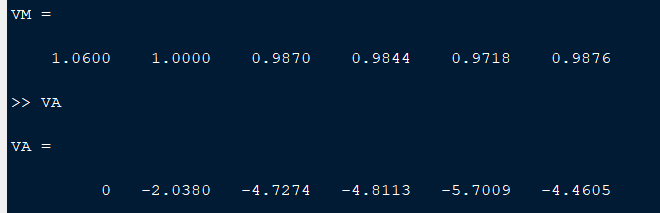

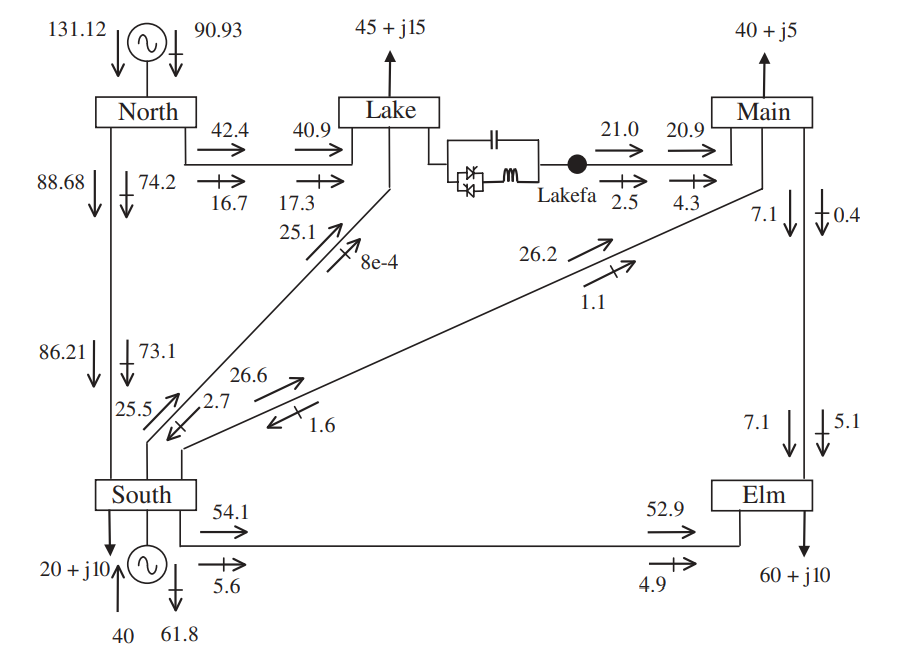

### Referencias:

[1] Gomez - Exposito,A. Electrica Energy Systems, Analysis and operation. 2nd Edition. Boca Raton : Taylor & Francis, CRC Press, 2018.

[2] Acha,E. FACTS Modelling and Simulation in Power Networks. 1st Edition. Boca Raton : John Wiley & Sons Inc,2004 